[y,fs]=audioread('prueba.m4a')

y =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


fs = 48000

N=length(y); 
yavg=(2/N)*sum(abs(y(1:ceil(N/2)))); 
yrms=sqrt((1/N)*sum(y.^2)); 
yrms=yrms(1,1)

yrms = 0.0286

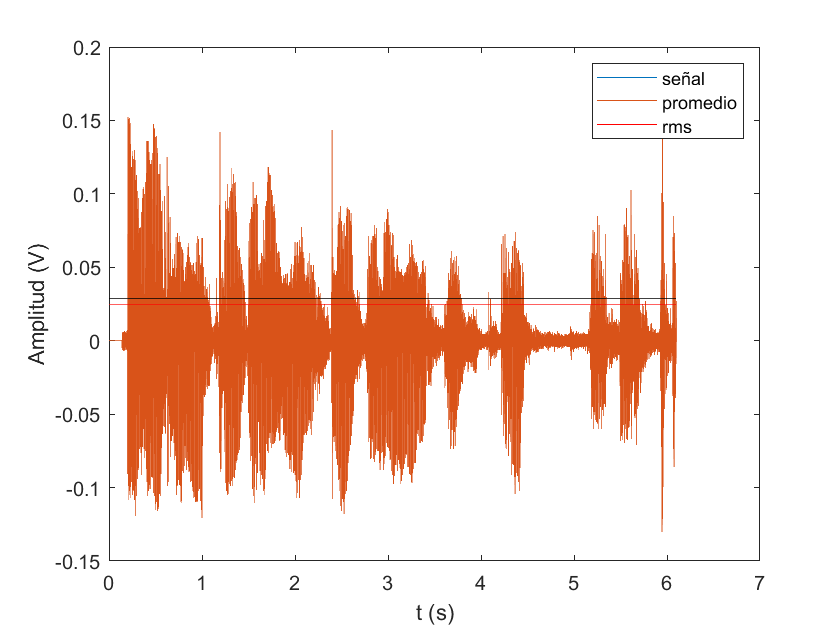

t=0:1/fs:N/fs;
plot(t(1:N),y)
hold on
plot(t,yavg*ones(size(t)),'r')
plot(t,yrms*ones(size(t)),'k')
hold off
xlabel('t (s)')
ylabel('Amplitud (V)')
legend('señal','promedio','rms')

audiowrite('outs.wav',y,s)


record(4,Fs);